作异形彩色标记线条图

## 语法

## 示例

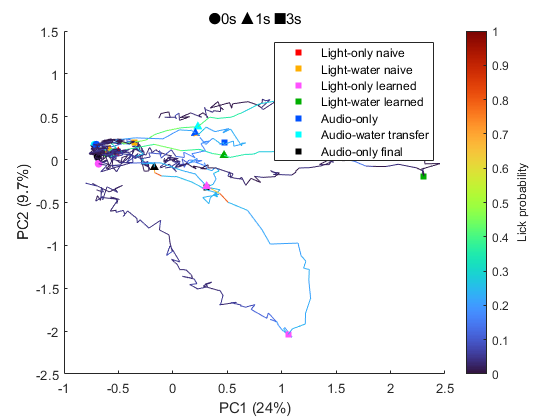

## 输入参数

Points(:,:,2:3)double，线上采样点的坐标。第1维时间，第2维不同的线，第3维XYZ。根据第3维长度决定画2D还是3D图。

LineColors(:,:,3)double，渐变的线条颜色。第1维时间，第2维不同的线，第3维RGB。前两维尺寸必须和Points相同，即对每个时点、每根线指定一种颜色。

MarkerIndex(1,:)uint16，标记时点位置，将在每条线的这些时点上添加标记。这里的时点是采样时点索引，不是真实时间。通常需要用真实时间×采样率。

MarkerShape(1,:)char，对应每个MarkerIndex位置，使用指定的符号标注。此功能依赖scatter或scatter3实现，详见Scatter.Marker属性文档。相同MarkerIndex的位置使用相同的MarkerShape。

MarkerColors(:,3)double，每条线上使用的标记颜色，不同线上颜色不同，一条线上颜色相同。第1维时间，第2维RGB。

## 返回值

Scatters(:,:)matlab.graphics.chart.primitive.Scatter，对每个标记返回一个Scatter对象，第1维对应不同的线，第2维对应不同时点（亦即不同形状）的标记。

**See also **[scatter](matlab:doc scatter) [scatter3](matlab:doc scatter3) [matlab.graphics.chart.primitive.Scatter](matlab:doc matlab.graphics.chart.primitive.Scatter)[](matlab:doc legend)

function Scatters = ColorfulMarkerPlot(Points,LineColors,MarkerIndex,MarkerShape,MarkerColors)
if ~isequal(size(Points,1:2),size(LineColors,1:2))
	UniExp.UniExpException.The_first_two_dimensions_of_Points_and_LineColors_are_different.Throw;
end
[NumLines,NumDimensions]=size(Points,2,3);
Points(end+1,:,:)=NaN;
LineColors(end+1,:,:)=NaN;
switch NumDimensions
	case 2
		patch(Points(:,:,1),Points(:,:,2),LineColors,EdgeColor='flat',FaceColor='none');
	case 3
		patch(Points(:,:,1),Points(:,:,2),Points(:,:,3),LineColors,EdgeColor='flat',FaceColor='none');
	otherwise
		UniExp.UniExpException.Wrong_array_size.Throw('Points第3维长度只能是2或3');
end
hold on
NumShapes=numel(MarkerShape);
Scatters=gobjects(NumLines,NumShapes);
Points=Points(MarkerIndex,:,:);
for S=1:NumShapes
	for L=1:NumLines
		switch NumDimensions
			case 2
				Scatters(L,S)=scatter(Points(S,L,1),Points(S,L,2),MarkerShape(S),MarkerEdgeColor='none',MarkerFaceColor='flat',CData=MarkerColors(L,:));
			case 3
				Scatters(L,S)=scatter3(Points(S,L,1),Points(S,L,2),Points(S,L,3),MarkerShape(S),MarkerEdgeColor='none',MarkerFaceColor='flat',CData=MarkerColors(L,:));
		end
	end
end